% Clear workspace and command window
clear;
clc;

% Read data from the Excel file
data = readtable('Rainfall_MM_Loggers_monthly_SUM.csv');

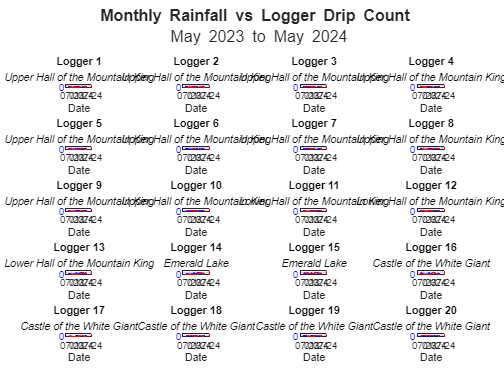


% Extract dates, rainfall, and drip count data
dates = data{:, 1}; %time is in column 1
rainfall = data{:, 2}; %rainfall is in column 2
drip_count = data{:, 3:22}; % Drip count is in columns 3 to 22

% Create a figure with 20 subplots
figure; clf
tiledlayout(5,4, 'TileSpacing','tight');

subtitles = {
    'Upper Hall of the Mountain King', 'Upper Hall of the Mountain King', 'Upper Hall of the Mountain King', ...
    'Upper Hall of the Mountain King', 'Upper Hall of the Mountain King', 'Upper Hall of the Mountain King', ...
    'Upper Hall of the Mountain King', 'Upper Hall of the Mountain King', 'Upper Hall of the Mountain King', ...
    'Upper Hall of the Mountain King', 'Lower Hall of the Mountain King', 'Lower Hall of the Mountain King', ...
    'Lower Hall of the Mountain King', 'Emerald Lake', 'Emerald Lake',  'Castle of the White Giant'...
    'Castle of the White Giant', 'Castle of the White Giant', 'Castle of the White Giant', 'Castle of the White Giant'...
};

for i = 1:20
    nexttile 
    yyaxis left;
    plot(dates, rainfall, 'b'); 
    ylabel('Rainfall (mm)', 'Color', 'b');
    
    yyaxis right;
    plot(dates, drip_count(:,i), 'r'); 
    xlabel('Date');
    title(sprintf('Logger %d', i), 'FontSize', 9);
    ylabel('Drip Count', 'Color', 'r');
    
    
    datetick('x', 'mm/yy', 'keepticks'); 
    xtickangle(0);
    grid on; 
    axis padded;
   
    subtitle(subtitles{mod(i-1, length(subtitles)) + 1}, 'FontSize', 2, 'FontAngle', 'italic'); 
    ax = gca; 
    ax.YAxis(1).Color = 'b'; 
    ax.YAxis(2).Color = 'r';
    ax.YAxis(2).Exponent = 0;
end

sgtitle({'\bfMonthly Rainfall vs Logger Drip Count', ' May 2023 to May 2024'});